# Mesh Generation

## Figure geometry 

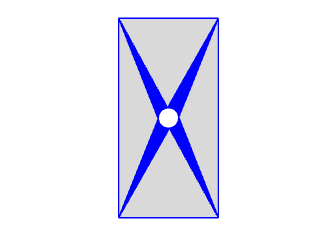

clear;

TR = stlread("PlateHolePlanar.stl");
nodes = (TR.Points(:,1:2))';
elements = (TR.ConnectivityList)';
edges = freeBoundary(TR)';

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','blue');
axis equal off
exportgraphics(gca,'PlateHolePlanar-Geo.pdf','ContentType','vector');

## Import Geometry from STL File

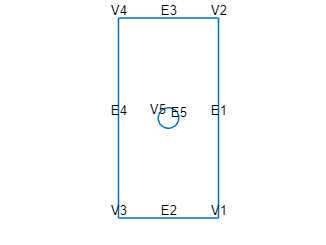

model = createpde;
importGeometry(model,"PlateHolePlanar.stl");
figure; 
pdegplot(model,VertexLabels = "on",EdgeLabels = "on");
axis equal off

## Example 1: Default

### Mesh generation 

mesh = generateMesh(model, GeometricOrder = "linear");
nodes = mesh.Nodes; elements =mesh.Elements;

### Figure Mesh

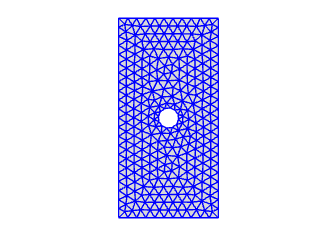

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'PlateHolePlanar-MeshDefault.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

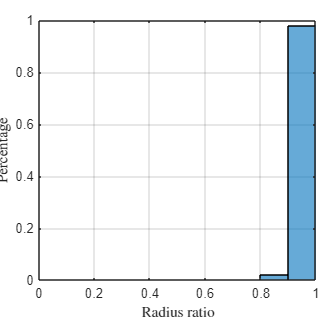

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 2: Hgrad

### Mesh generation 

mesh = generateMesh(model, GeometricOrder = "linear", Hgrad=1.1);
nodes = mesh.Nodes; elements =mesh.Elements;

### Figure Mesh

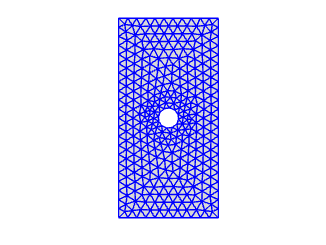

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'PlateHolePlanar-MeshHgrad.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

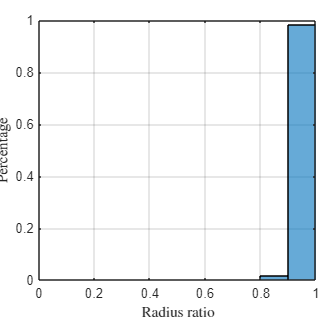

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on